# 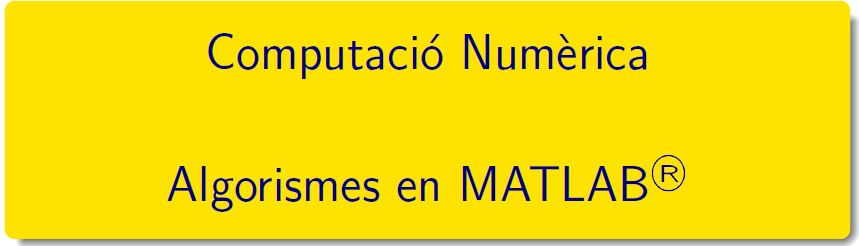

# Pràctica 1 - Conceptes Bàsics

## 1. Introducció a MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

## 2. Exemple mètode iteratiu: convergència 

El mètode iteratiu següent: convergeix a $\sqrt{2}$


$$x_k=\displaystyle\frac{1}{2}\left (x_{k-1}+\displaystyle\frac{2}{x_{k-1}}\right )\quad k\ge 1\ i\ x_0=3\,.$$


Calcular el valor $$x_{10}$$ fent ús de les instruccions

- bucle for

- bucle while

En tots els casos comparar el resultat obtingut amb el valor $$\sqrt{2} $$ . 

Calculeu els decimals correctes i les cifres significatives en cada iteració. Presenteu els resultats obtinguts en una taula.

**Solucions**

Calculem 5  iterats, no conservem els valors càlculats

format short
i = 0;
z = 3; %xo = 3;
while (i < 5)
    z = 1/2*(z+(2/z))
    i = i+1;
end
%Calculem error absolut i decimals correctes
ea = abs(sqrt(2)-z)
dc = fix(-log10(2*ea))   % error absolut i decimals correcte, també és correcte sense el 2*, 
% simplement és un factor que et desplaça res important

Calculem 5 iterats, conservem els valors càlculats

format short
i = 1; %per a vectors començar amb 1 millor sino accedim a 0 i se queixa
v = [];
v(1) = 3;
while (i <= 5)
    v(i+1) = 1/2*(v(i)+(2/v(i)));
    i = i+1;
end
v(2:end) %tenim els 5 iterats calculats
er = ea/sqrt(2)         % error relatiu
XS = fix(-log10(2*er))  % xifes significatives, sense el 2 també és correcte!

Calculeu els 5 primers iterats, totes les iteracions en un vector, resultat en una estructura table.

format short
i = 1; %per a vectors començar amb 1 millor sino accedim a 0 i se queixa
v = [];
v(1) = 3;
while (i <= 5)
    v(i+1) = 1/2*(v(i)+(2/v(i)));
    i = i+1;
end

format shortG
ea = abs(v-sqrt(2)); 
dc = fix(-log10(2*ea));   % error absolut i decimals correcte
er = ea/sqrt(2); 
XS = fix(-log10(2*er));
R = [0:i-1;v;ea;dc;er;XS]';

TR = array2table(R,'VariableNames',{'k','v','error absolut','decimals correctes','error relatiu','xifres significatives'});
disp(TR)

### Qüestió oberta

Calculeu els ¿¿¿tots ???  els iterats, com s'atura el bucle

x = [];
x(1) = 3;   % x0=3
ea(1) = 1;
i = 1;
n = 50; %nombre iteracions

while (i <= 50 && ea(i)>eps)
    x(i+1) = 1/2*(x(i)+(2/x(i)));
    ea(i+1) = abs(x(i+1)-sqrt(2));
    i = i+1;
end

format shortG
ea = abs(x-sqrt(2));      % error absolut
dc = fix(-log10(2*ea));   % decimals correcte
er = ea/sqrt(2);          % error relatiu
XS = fix(-log10(2*er));   % xifres significatives
R = [0:i-1;x;ea;dc;er;XS]';
TR = array2table(R,'VariableNames',{'k','x','error absolut','decimals','error relatiu','xifres'}); 
disp(TR)

## 3. Aritmètica de PUNT FLOTANT

The memory format of an IEEE 754 double-precision floating-point value.

$fl(x)=(-1)^s\cdot \left(1+\frac{F}{2^{52}}\right)\cdot 2^{E-1023}$ per $s$ un bit, per $E$, l'exponent $11$ bits i per $F$, la part fraccionaria $52$bits

 Illustrated in byte-form, the exponent and fraction bits are distributed as:

[image: IEEE_754_Double_Floating_Point_Format.svg]   [crèdits imatge](https://commons.wikimedia.org/wiki/File:IEEE_754_Double_Floating_Point_Format.svg)

*0*0000000 0000**0000 00000000 00000000 00000000 00000000 00000000 00000000**

[Floating Point Arithmetic Before IEEE 754](https://blogs.mathworks.com/cleve/2019/01/18/floating-point-arithmetic-before-ieee-754/)

[A Glimpse into Floating-Point Accuracy](https://blogs.mathworks.com/loren/2006/08/23/a-glimpse-into-floating-point-accuracy/?s_tid=srchtitle)  o  [Floating Point Numbers](https://es.mathworks.com/help/matlab/matlab_prog/floating-point-numbers.html)

**Exercici 1.- Nombres binaris i nombres decimals**

- Convertim el nombre 9.5 a binari:

x = 18.25

x =         18.25


- part entera, restes de dividir per 2

y = fix(x); x = rem(y,2); T = [y,x];
y = fix(y/2); x = rem(y,2); T = [T; y,x];
y = fix(y/2); x = rem(y,2); T = [T; y,x];
y = fix(y/2); x = rem(y,2); T = [T; y,x];
y = fix(y/2); x = rem(y,2); T = [T; y,x],

T =     18     0
     9     1
     4     0
     2     0
     1     1



b = num2str(T(end:-1:1,2));
fprintf('El nombre %f en binari és %s\n',fix(x),b)

El nombre 18.000000 en binari és 10010


- part fraccionaria, multipliquem per 2 i ens quedem amb la part entera

z = x-fix(x);
y = 2*z; x = fix(y);  T = [z,x]; z = y-x;
y = 2*z; x = fix(y);  T = [T; z,x], z = y-x;

T =          0.25            0
          0.5            1


b2 = num2str(T(:,2));
fprintf('El nombre %f en binari és %s\n',x-fix(x),b2)

El nombre 0.250000 en binari és 01


fprintf('El nombre %f en binari és %s.%s\n',x,b,b2)

El nombre 18.250000 en binari és 10010.01


**Exercici 2.- Aritmètica de punt flotant de 64 bits**

### LECTURA OBLIGATÒRIA: [Floating Points: IEEE Standard Unifies Arithmetic Model](https://es.mathworks.com/company/newsletters/articles/floating-points-ieee-standard-unifies-arithmetic-model.html?s_tid=answers_rc2-3_p6_Topic)

Toby Driscoll (2021). IEEE 754 binary representation ([https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation),](https://www.mathworks.com/matlabcentral/fileexchange/25326-ieee-754-binary-representation),) MATLAB Central File Exchange. Retrieved February 17, 2022.

[S,E,F] = ieee754(17)

### **Exemples**

**Avoiding Common Problems with Floating-Point Arithmetic**

Example 1 — Round-Off or What You Get Is Not What You Expect

- 4/3 no té fracció binària exacte

a = 4/3

a = 1.3333

b = a-1

b = 0.3333

c = b+b+b

c = 1.0000

e = 1-c

e = 2.2204e-16

[S,E,F] = ieee754(4/3)

S = '0'

E = '01111111111'

F = '0101010101010101010101010101010101010101010101010101'

- 0.1 no té representació binària exacte

[S,E,F] = ieee754(0.1)

S = '0'

E = '01111111011'

F = '1001100110011001100110011001100110011001100110011010'

a = 0.0;
for i = 1:10
  a = a + 0.1;
end
a == 1

ans = logical
   0


- L'ordre de les operacions pot fer variar el resultat del càlcul

format longG
b = 1e-16 + 1 - 1e-16;
c = 1e-16 - 1e-16 + 1;
b == c

ans = logical
   0


- Hi ha "gaps" entre els números de punt flotant.  

(2^53 + 1) - 2^53

ans =      0


- La representació de $\pi$ comporta que 

sin(pi), sin(pi) == 0

ans =       1.22464679914735e-16


ans = logical
   0


**Example 2 — Catastrophic Cancellation**

sqrt(1e-16 + 1) - 1

ans =      0


**Example 3 — Floating-Point Operations and Linear Algebra**

L'arrodoniment, la cancel·lació i altres caracterítiques de l'aritmètica de coma flotant es combinen per produir càlculs sorprenents en resoldre els problemes de l'àlgebra lineal. MATLAB adverteix que la següent matriu A està mal condicionada i, per tant, el sistema Ax = b pot ser sensible a petites pertorbacions:

% A = diag([2 eps]); b = [2; eps]; y = A\b
A1=[2 -4; -3, 6.001]; b=[1;2]; x=A1\b, determinant = det(A1)

x =           7000.49999999999
                      3500


determinant =                      0.002


A2=[2 -4; -2.998, 6.001]; b=[1;2]; x=A2\b, determinant = det(A2)

x =           1400.09999999993
          699.799999999963


determinant =         0.0100000000000005


cond(A) %cal veure com de gran és el nombre de condició per adonar-nos de que el problema és mal condicionat

ans =           6500.00034614984


**Example 4 — "Soroll numèric"**

x = 0.988:.0001:1.012;
y = x.^ 7- 7* x.^ 6+ 21* x.^ 5- 35* x.^ 4+ 35* x.^ 3 - 21* x.^ 2+ 7* x- 1;
z = (x-1).^7;
plot( x, y, x, z)

## 4. Algorismes: Estabilitat numèrica i problemes ben condicionats

### Practiquem les funcions

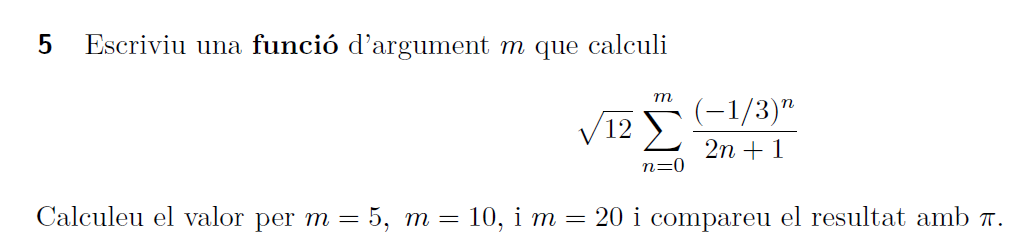

format long
syms n
calculF = @(m)double(sqrt(12) * symsum(((-1/3)^n)/(2*n+1), n, 0, m));
x = [];
m = 20;
i = 1;

while i <= m
    x(i) = calculF(i);
    i = i + 1;
end

ea = abs(pi - x);
er = ea/pi;
dc = fix(-log10(2*ea));   % decimals correcte
xs = fix(-log10(2*er));   % xifres significatives
R = [1:m;x;ea;dc;er;xs]';
TR = array2table(R,'VariableNames',{'k','x','Error Absolut','Decimals Correctes','Error Relatiu','Xifres Significatives'});
disp(TR)

    k            x               Error Absolut        Decimals Correctes       Error Relatiu        Xifres Significatives
    __    ________________    ____________________    __________________    ____________________    _____________________

     1      3.079201435678      0.0623912179117889             0              0.0198597414723696              1          
     2    3.15618147156995      0.0145888179801612             1             0.00464376499082115              2          
     3    3.13785289159568     0.00373976199411263             2             0.00119040321470046              2          
     4    3.14260474566308     0.00101209207329145             2            0.000322158912656918              3          
     5    3.14130878546288    0.000283868126909503             

**6** Avalueu les funcions 


$$\displaystyle f(x)=\sqrt{x^2+1}-1\,,\quad\quad
g(x)=x^2/{\left( \sqrt{x^2+1}+1\right) }$$


per a la successió de valors de $x_n= 8^{-n}\,,\ n\geq 1\,.$

Encara que $f(x)=g(x)$, l'ordinador dóna resultats diferents. 

Quins resultats són de fiar i quins no? Per què?  Expliqueu la vostra resposta

format shortG
f = @(x)sqrt(x.^2+1)-1;
g = @(x)x.^2./(sqrt(x.^2+1)+1);
k = 0:15;
y = 8.^(-k);
R =[k;y;f(y);g(y)]';
T = array2table(R,...
    'VariableNames',{'k','8^(-k)','f(8^-k)','g(8^-k)'}); 
disp(T)

    k       8^(-k)       f(8^-k)       g(8^-k)  
    __    __________    __________    __________

     0             1       0.41421       0.41421
     1         0.125     0.0077822     0.0077822
     2      0.015625    0.00012206    0.00012206
     3     0.0019531    1.9073e-06    1.9073e-06
     4    0.00024414    2.9802e-08    2.9802e-08
     5    3.0518e-05    4.6566e-10    4.6566e-10
     6    3.8147e-06     7.276e-12     7.276e-12
     7    4.7684e-07    1.1369e-13    1.1369e-13
     8    5.9605e-08    1.7764e-15    1.7764e-15
     9    7.4506e-09             0    2.7756e-17
    10    9.3132e-10             0    4.3368e-19
    11    1.1642e-10             0    6.7763e-21
    12    1.4552e-11             0    1.0588e-22
    13     1.819e-12             0    1.6544e-24
    14    2.2737e-13             0    2.5849e-26
    15    2.8422e-14          

**12** **Càlcul d'integrals per recurrència**	

	Per calcular les integrals$\displaystyle I_{n}=\int_{0}^{1} x^n e^{x-1}dx\,,\quad n\ge~1\,,$ 	dispossem de dos m\`{e}todes iteratius diferents:

	
$$$$\begin{array}{llrr}
	\text{ a)}\quad I_{n-1}&=\displaystyle\frac{1-I_n}{n}, & n\ge 2 &{\rm\ on\ }I_{50}=0\,,\\  & & & \\
	\text{ b)}\quad I_n&=1-nI_{n-1}, & n\ge 2 &{\rm\ on\ }I_1=1/e\,.
	\end{array}$$$$


	Calculeu $$I_{30}$\,$ pels dos mètodes. Obteniu els mateixos resultats ? Sabrieu donar una explicació?

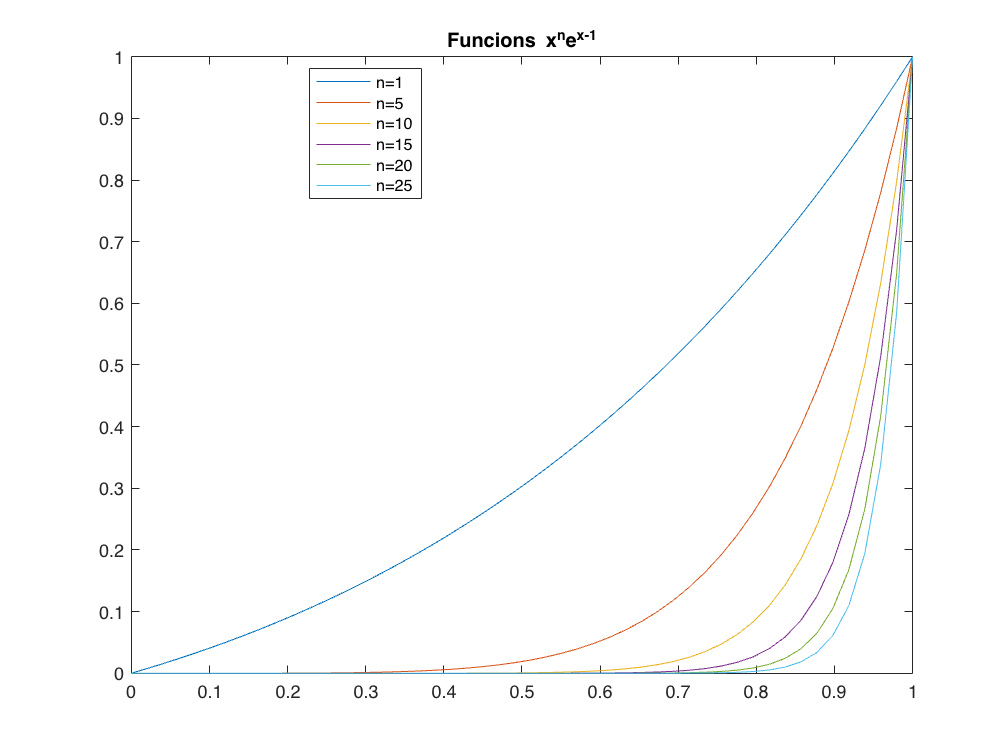

F = @(x,n)x.^n.*exp(x-1);
t = linspace(0,1,50);
plot(t,F(t,1)),hold on
for k=1:5
    plot(t,F(t,k*5))
end
hold off
title('Funcions x^ne^{x-1}'),legend('n=1','n=5','n=10','n=15','n=20','n=25','Location','best')

- apartat a)

J(50) = 0;
for k=50:-1:2
    J(k-1) = (1-J(k))/k;
end

- apartat b)

I(1) = exp(-1);
for k=2:50
    I(k) = 1-k*I(k-1);
end

- valor aproximat per integració numèrica

for j=1:50
    ve(j) = integral(@(x)x.^j.*exp(x-1),0,1);
end

- Taula comparativa de resultats

k=1:50;
R =[k;ve;J;I]';
T = array2table(R,...
    'VariableNames',{'k','ve','apartat a)','apartat b)'}); disp(T)

    k        ve       apartat a)    apartat b) 
    __    ________    __________    ___________

     1     0.36788      0.36788         0.36788
     2     0.26424      0.26424         0.26424
     3     0.20728      0.20728         0.20728
     4     0.17089      0.17089         0.17089
     5     0.14553      0.14553         0.14553
     6      0.1268       0.1268          0.1268
     7     0.11238      0.11238         0.11238
     8     0.10093      0.10093         0.10093
     9    0.091612     0.091612        0.091612
    10    0.083877     0.083877        0.083877
    11    0.077352     0.077352        0.077352
    12    0.071773     0.071773        0.071773
    13    0.066948     0.066948        0.066948
    14    0.062732     0.062732        0.062731
    15    0.059018     0.059018        0.059034
    16    0.055719     0.055719        0.055459

- Taula comparativa d'errors

Re =[k;abs(ve-J);abs(ve-I)]';
Te = array2table(Re,...
    'VariableNames',{'k','apartat a)','apartat b)'}); disp(Te)

    k     apartat a)    apartat b)
    __    __________    __________

     1    5.5511e-17    5.5511e-17
     2    5.5511e-17    5.5511e-17
     3    5.5511e-17    1.1102e-16
     4             0    2.7756e-16
     5    2.7756e-17    1.4988e-15
     6             0    8.9373e-15
     7    1.3878e-17    6.2658e-14
     8             0    5.0113e-13
     9    1.3878e-17    4.5102e-12
    10    1.3878e-17    4.5101e-11
    11    1.3878e-17    4.9612e-10
    12    1.3878e-17    5.9534e-09
    13    1.3878e-17    7.7394e-08
    14             0    1.0835e-06
    15    6.9389e-18    1.6253e-05
    16    6.9389e-18    0.00026004
    17    1.3878e-17     0.0044208
    18    6.9389e-18      0.079574
    19    6.9389e-18        1.5119
    20    1.3878e-17        30.238
    21             0           635
    22    6.9389e-18         13970
    23    6.9389e-18    3.2131e+05
    24             0  

## Pràctica

## 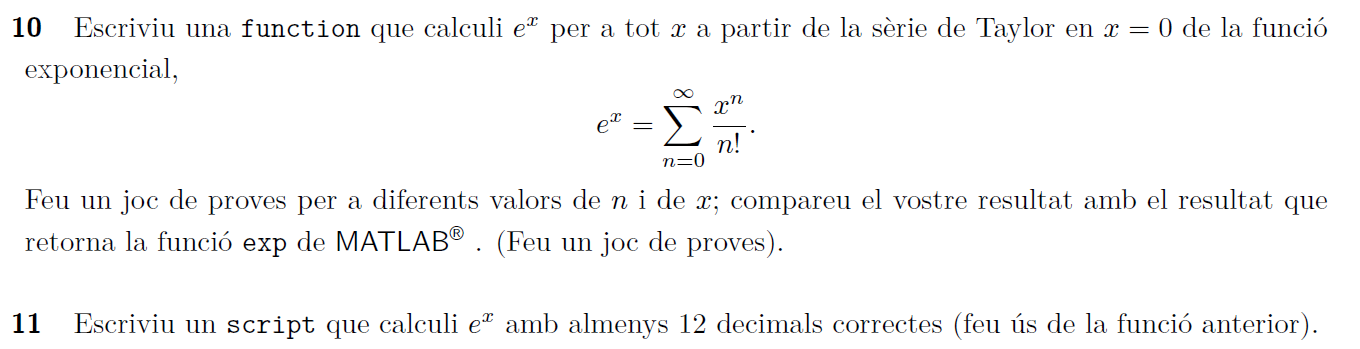 

sym n;
e = @(x) symsum((x^n)/factorial(n), n, 0, 50000); %no compila?
e(3)

Check for incorrect argument data type or missing argument in call to function 'symsum'.

Error in Prac01_grup12 (line 160)
e = @(x) symsum((x^n)/factorial(n), n, 0, 50000); %no compila?

`Document preparat per M. Àngela Grau Gotés, 17 de febrer de 2022`